# Probabilistic Principle Component Analysis For Time Delay Interferometry

Quentin Baghi has introduced a method to construct the TDI combinations with Principle Component Analysis (PCA). The travelling time of the light between two distant spacedracfts is not required in this method.

Now, we propose an method to form the TDI combinations with PCA from the perspective of probability, and it helps us to deal with the missing data case. We call this method as PPCA-TDI.

## Data Simulation

Like Baghi, we use the simulated data to validate the PPCATDI. The following equations show the noise requirements of LISA.

- Laser frequency noise: $S_{p}(f)=\left(\frac{28.2 \mathrm{~Hz} \cdot \mathrm{Hz}^{-1 / 2}}{\nu_{0}}\right)^{2},$

- Stochastic noise: $S_{n}(f)=\frac{S_{a}(f)}{(2 \pi f c)^{2}}+\left(\frac{2 \pi f}{c}\right)^{2} S_{\mathrm{oms}}(f),$

where $\nu_0 =\frac{c}{1064\times {10}^{-9} \;\mathrm{m}}$ is the central frequency of the lasers, $S_a \left(f\right)$ is the test-mass acceleration noise PSD (in ${\mathrm{m}}^2 {\mathrm{s}}^{-4} {\textrm{Hz}}^{-1}$) and $S_{\textrm{oms}} \left(f\right)$ is the PSD representing all other path length noises in the measurement (in ${\mathrm{m}}^2 {\textrm{Hz}}^{-1}$).

- Test-mass acceleration noise: $S_a \left(f\right)=a_{\textrm{TM}}^2 \left\lbrack 1+{\left(\frac{f_1 }{f}\right)}^2 \right\rbrack \left\lbrack 1+{\left(\frac{f}{f_2 }\right)}^4 \right\rbrack ,$

- Optical metrology system (OMS) noise: $S_{\textrm{oms}} \left(f\right)=a_{\textrm{oms}}^2 \left\lbrack 1+{\left(\frac{f_3 }{f}\right)}^4 \right\rbrack \ldotp$

where $a_{\textrm{TM}} =3\times {10}^{-15} {\;\textrm{ms}}^{-2} ,a_{\textrm{oms}} =15\times {10}^{-12} {\;\textrm{mHz}}^{-\frac{1}{2}} ,f_1 =4\times {10}^{-4} \;\textrm{Hz},f_2 =8\times {10}^{-3} \;\textrm{Hz},f_3 =2\times {10}^{-3} \;\textrm{mHz}\ldotp$

clc;
clear;
close all;
warning off;
load lowpass1.mat lowpass1
load lowpass.mat lowpass

% -------- %
% constant %
% -------- %
global fs len dura c L n_h p AUs year
% simulation parameter
% sampling rate
fs = 2;                                 % in Hz
% duration of simulation
dura =43200;   % in seconds
% length of samples
len = fs * dura;
% speed of light
c = 299792458;                          % in m/s
% armlength of Taiji
L = 3e9;                                % in m
% Astronomical unit
AUs = 499.00478383615643;               % in seconds
% year
year = 31558149.763545603;              % in seconds
% length of filter          
len_filter = 101;
% nh
n_h = 25;
% p
p = n_h * 2 + 1;
% PSDs parameter
nu_0 = c / (1064e-9);                   % in Hz
a_TM = 3e-15;                           % in m/s
a_oms = 15e-12;                         % in m/s^{1/2}
f_0 = 2e-3;                             % in Hz
f_1 = 4e-4;                             % in Hz
f_2 = 8e-3;                             % in Hz
f_3 = 2e-6;                             % in Hz

% -------------- %
% PSDs of noises %
% -------------- %
% test-mass acceleration noise
S_a = @(f) sqrt(a_TM^2 * (1 + (f_1 ./ f).^2) .* (1 + (f / f_2).^4)) * sqrt(2);
% OMS noise
S_oms = @(f) sqrt(2) * sqrt(a_oms^2 * (1 + (f_3 ./ f).^4));
% stochastic noise
S_n = @(f) sqrt(2) * sqrt(a_TM^2 .* (1 + (f_1 ./ f).^2) .* (1 + (f / f_2).^4) ./ ...
    (2 .* pi .* f .* c).^2 + (2 .* pi .* f ./ c).^2 .* a_oms^2 .* (1 + (f_3 ./ f).^4));
% laser frequecny noise
S_p = @(f) sqrt(2) * sqrt((28.2 / nu_0)^2 * f ./ f);

% time series of noises
% white noise
white = wgn(len, 9, 0);
f = 1e-4: 1e-5: 1e-1;
% laser frequency noise, three spacescrafts => three laser frequency noises
laser_freq_noise = time_series_from_asd(S_p, white(:, 1: 3), fs) * sqrt(fs/2);
% stochastic noise, six links => six stochastic noises
stochastic_noise = time_series_from_asd(S_n, white(:, 4: 9), fs) * sqrt(fs/2);
% color space
% light
c_l = [
    "#FFCDD2", ...
    "#F8BBD0", ...
    "#CE93D8", ...
    "#B1CEFF", ...
    "#B9ECF3", ...
    "#B2DFDB", ...
    "#AED581", ...
    "#DCE775", ...
    "#FFEB3B", ...
    "#FFB74D"
    ];
% dark
c_d = [
    "#890519", ...
    "#F06292", ...
    "#AB47BC", ...
    "#266EE8", ...
    "#26C6DA", ...
    "#009688", ...
    "#7CB342", ...
    "#AFB42B", ...
    "#F57F17", ...
    "#EF6C00"
    ];

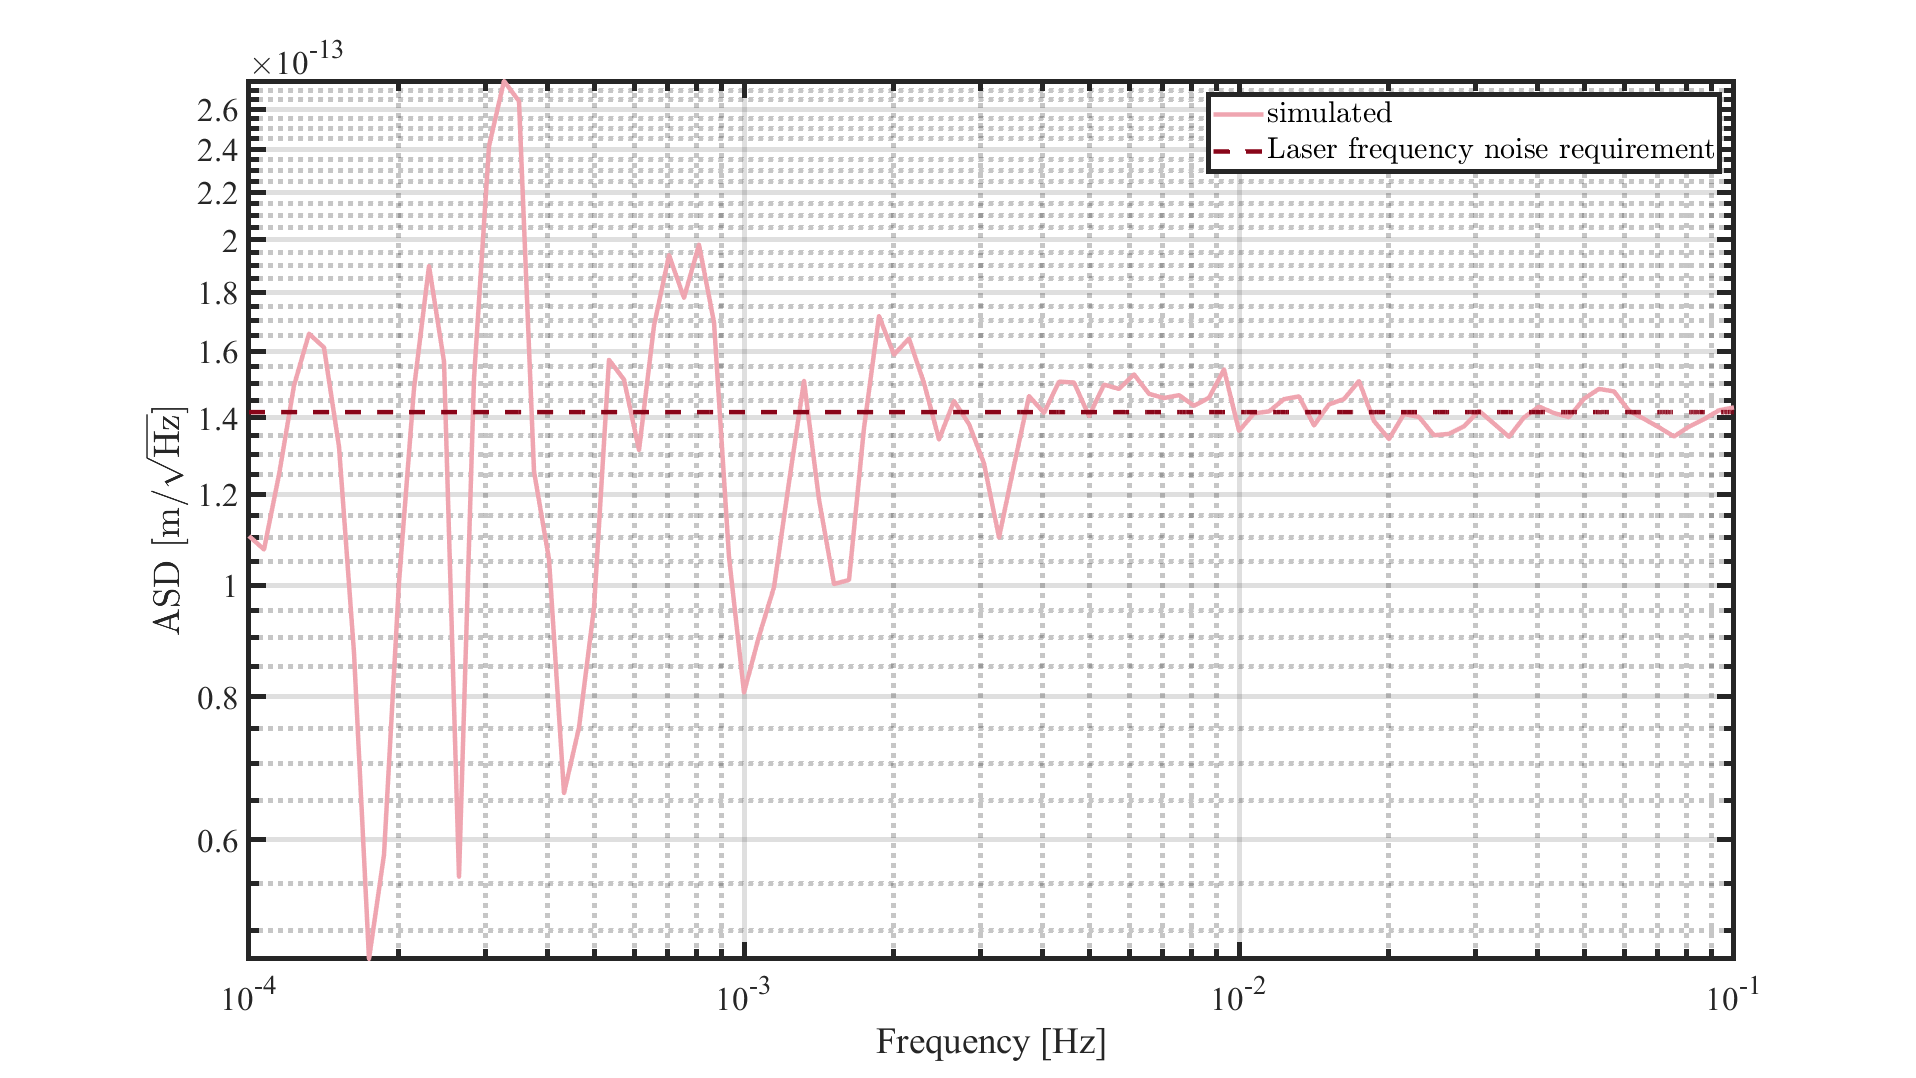

% plot psds
new_figure;
[X_laser, f_laser, C_laser] = lpsd(laser_freq_noise(:, 1), @hann, ...
    1e-4, 1e-1, 100, 1, 1, fs, 0.9);
loglog(f_laser, sqrt(X_laser .* C_laser.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f, S_p(f), 'linewidth', 2.7, "LineStyle", "--", "Color", "#890519");
legend("simulated", ...
    "Laser frequency noise requirement", ...
    "interpreter", "latex")
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

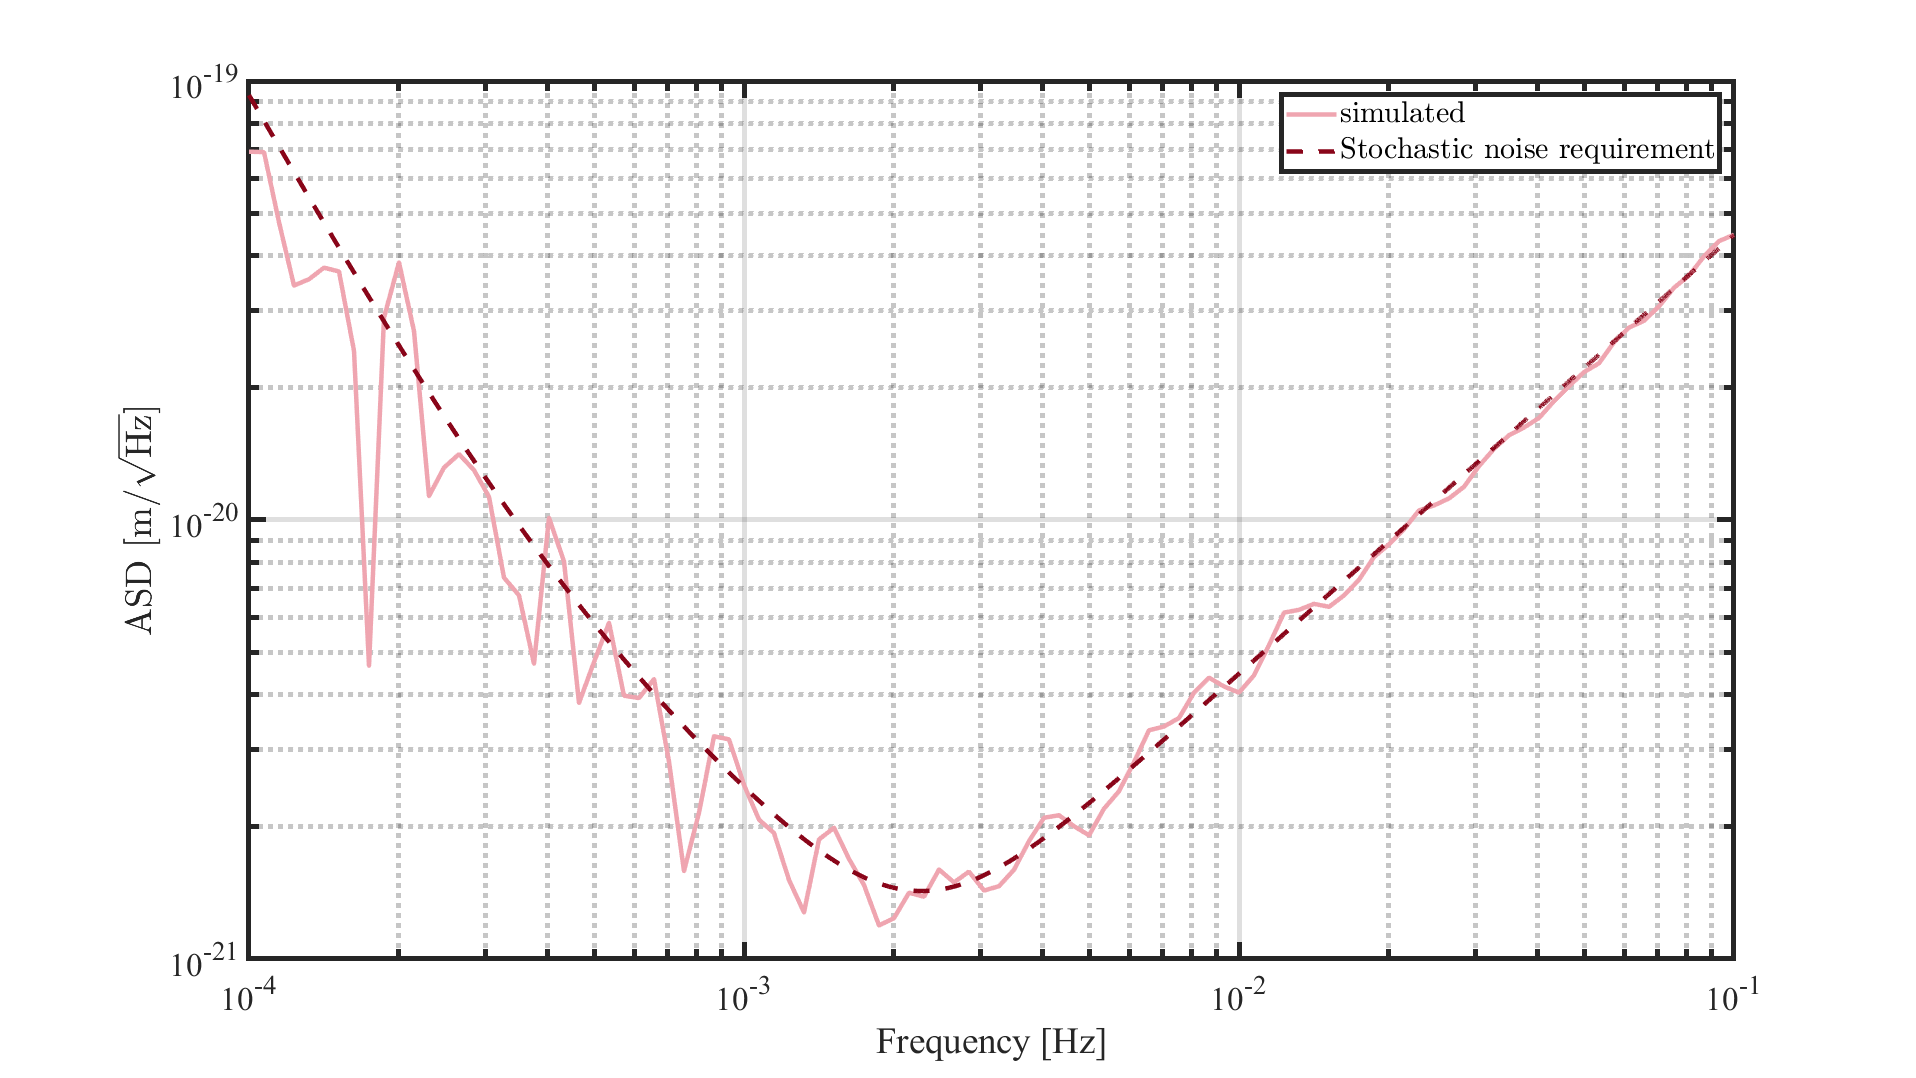

new_figure;
[X_stocha, f_stocha, C_stocha] = lpsd(stochastic_noise(:, 1), ...
    @hann, 1e-4, 1e-1, 100, 1, 1, fs, 0.9);
loglog(f_stocha, sqrt(X_stocha .* C_stocha.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f, S_n(f), 'linewidth', 2.7, "LineStyle", "--", "Color", "#890519");
legend("simulated", ...
    "Stochastic noise requirement", ...
    "interpreter", "latex")
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

We assume that Taiji's single-link measurements include two main sources of noise: a large term due to laser frequency fluctuations and a much smaller term due to other instrumental noises. We assume that the signals measured by the two optical benches on board spacecraft 1 are given by the equations


$$\begin{array}{l}
s_{12} \left(t\right)=p_{21} \left(t-\frac{L_{12} }{c}\right)-p_{12} \left(t\right)+n_{12} \left(t\right),\\
s_{13} \left(t\right)=p_{31} \left(t-\frac{L_{13} }{c}\right)-p_{13} \left(t\right)+n_{13} \left(t\right),
\end{array}$$


where $p_{\textrm{ij}}$ are laser noises, $n_{\textrm{ij}}$ are secondary noises, and $c$ is the speed of light. To simplify the analysis, we assume that the two lasers on board each spacecraft $i$ are identical, so that $p_{\textrm{ij}} =p_{\textrm{ik}}$. In this model, the measured laser noises can be seen as the result of the mixing (and delaying) of a vector of laser noise sources $\mathit{\mathbf{p}}={\left({\mathit{\mathbf{p}}}_{12}^T ,{\mathit{\mathbf{p}}}_{23}^T ,{\mathit{\mathbf{p}}}_{31}^T \right)}^T$. We consider the 6$N$ column-vector version of the $N\times 6$ matrix $\mathit{\mathbf{Y}}$, which stacks all the measurements as 


$$\mathit{\mathbf{y}}={\left({\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} \right)}^{\mathit{\mathbf{T}}} ,$$


This mixing is represented by a $6N\times 3N$ design matrix $M$, such that the model for $\mathit{\mathbf{y}}$ is


$$\mathit{\mathbf{y}}=\textrm{Mp}+\mathit{\mathbf{n}},$$


where we set $\mathit{\mathbf{n}}={\left({\mathit{\mathbf{n}}}_{12}^{\mathit{\mathbf{T}}} ,\ldotp \ldotp \ldotp ,{\mathit{\mathbf{n}}}_{32}^{\mathit{\mathbf{T}}} \right)}^{\mathit{\mathbf{T}}}$. Using this assumption, we have


$$\mathit{\mathbf{M}}=\left\lbrack \begin{array}{ccc}
-1 & {\mathit{\mathbf{D}}}_{12}  & 0\\
0 & -1 & {\mathit{\mathbf{D}}}_{23} \\
{\mathit{\mathbf{D}}}_{31}  & 0 & -1\\
-1 & 0 & {\mathit{\mathbf{D}}}_{13} \\
{\mathit{\mathbf{D}}}_{21}  & -1 & 0\\
0 & {\mathit{\mathbf{D}}}_{32}  & -1
\end{array}\right\rbrack ,$$


We assume a static Taiji constellation, that is, $L=3\times {10}^9 \;\mathrm{m}=L_{12} =L_{21} =L_{13} =L_{31} =L_{23} =L_{32}$. Therefore, ${\mathit{\mathbf{D}}}_{12} ={\mathit{\mathbf{D}}}_{21} ={\mathit{\mathbf{D}}}_{13} ={\mathit{\mathbf{D}}}_{31} ={\mathit{\mathbf{D}}}_{23} ={\mathit{\mathbf{D}}}_{32}$.

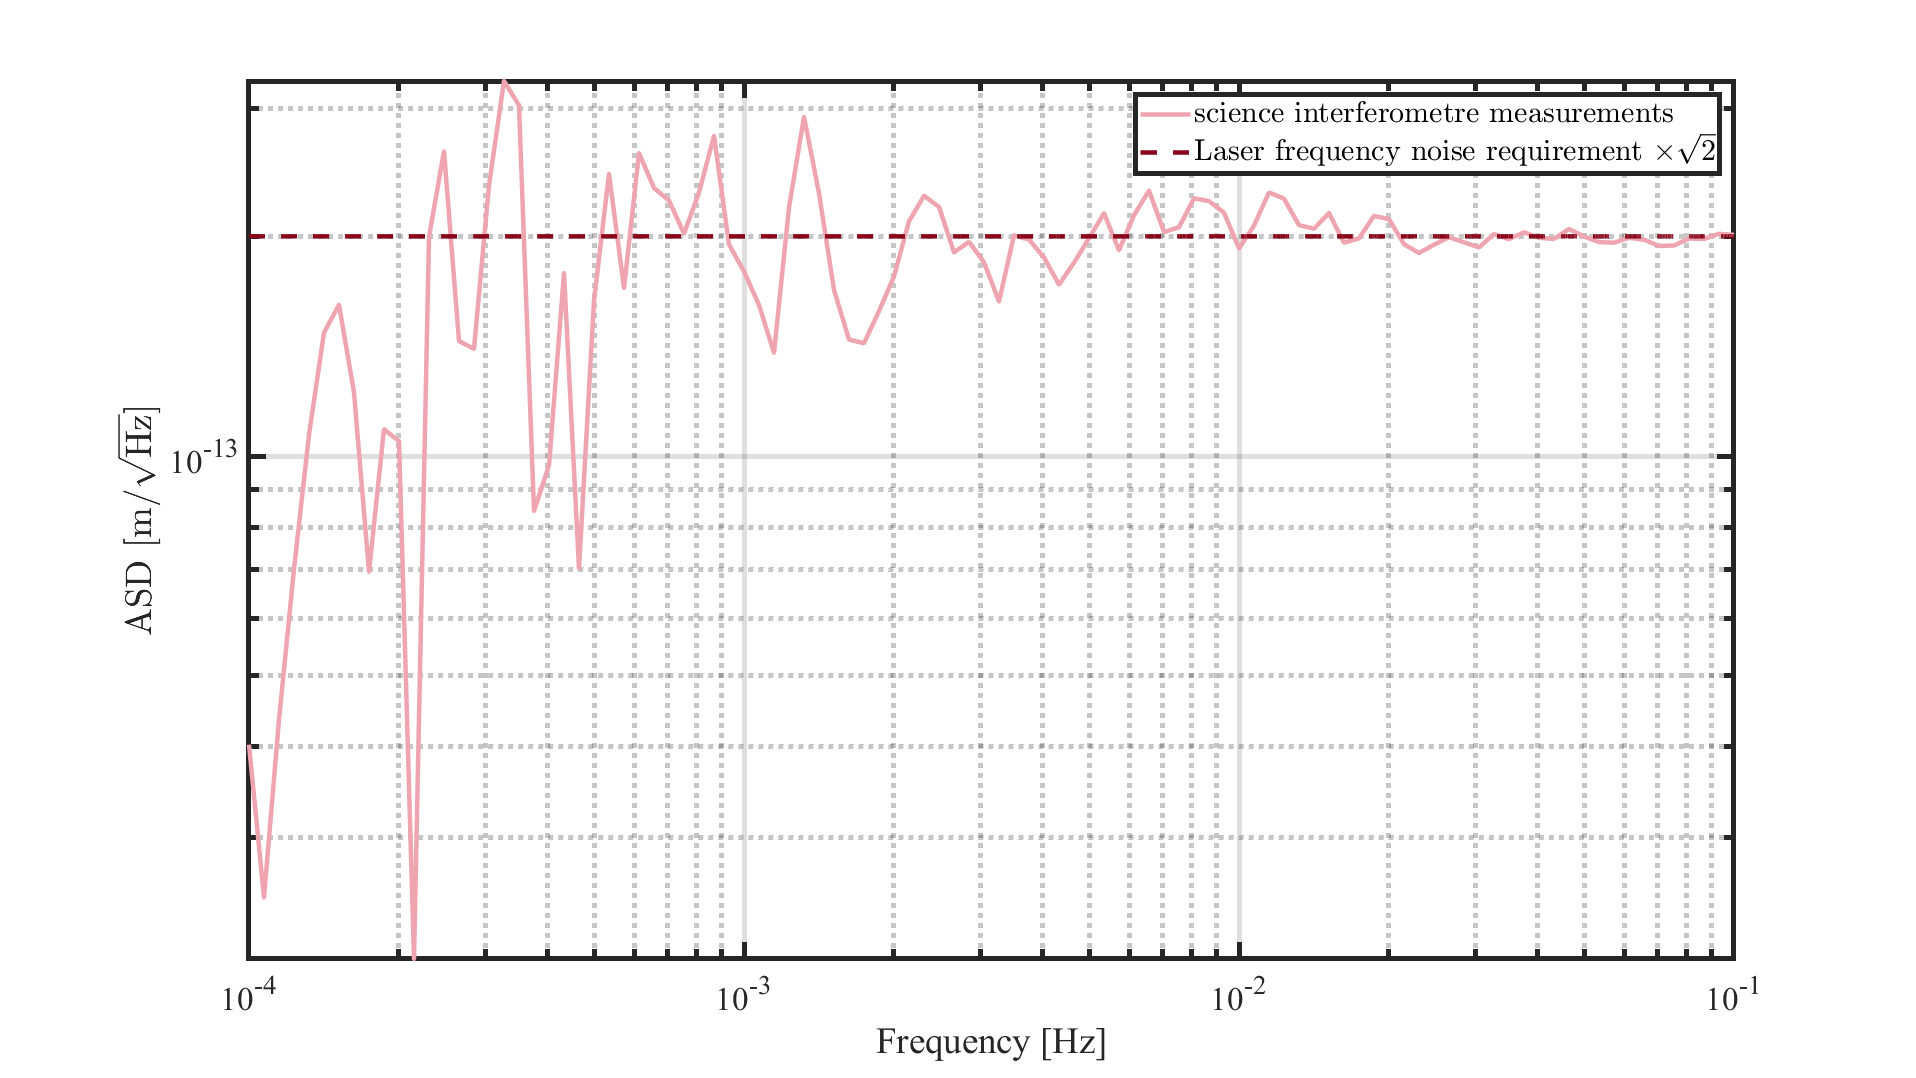

% --------------------------------------------------------------- %
% Form the single-link measurements of the science interferometer %
% --------------------------------------------------------------- %
% lagrange filter kernel, fractional delay filter, from shaddock
int_delay = floor(L/c*fs);
laser_freq_noise_delayed = timeshift(laser_freq_noise, repmat(L/c*fs, 3, 1), len_filter);
start_index_matched = round((len_filter - 1) / 2) + int_delay + 1;
if round((len_filter - 1) / 2) > int_delay
    end_index_matched = round((len_filter - 1) / 2) - int_delay;
    laser_freq_noise_matched = laser_freq_noise(start_index_matched: end - end_index_matched, :);
    stochastic_noise_matched = stochastic_noise(start_index_matched: end - end_index_matched, :);
else
    end_index_delayed = -round((len_filter - 1) / 2) + int_delay;
    laser_freq_noise_delayed = laser_freq_noise_delayed(1: end - end_index_delayed, :);
    laser_freq_noise_matched = laser_freq_noise(start_index_matched: end, :);
    stochastic_noise_matched = stochastic_noise(start_index_matched: end, :);
end

% measurements of science interferometer
s_12_no = laser_freq_noise_delayed(:, 2) - laser_freq_noise_matched(:, 1);
s_21_no = laser_freq_noise_delayed(:, 1) - laser_freq_noise_matched(:, 2);
s_13_no = laser_freq_noise_delayed(:, 3) - laser_freq_noise_matched(:, 1);
s_31_no = laser_freq_noise_delayed(:, 1) - laser_freq_noise_matched(:, 3);
s_23_no = laser_freq_noise_delayed(:, 3) - laser_freq_noise_matched(:, 2);
s_32_no = laser_freq_noise_delayed(:, 2) - laser_freq_noise_matched(:, 3);
s_12_ye = s_12_no + stochastic_noise_matched(:, 1);
s_21_ye = s_21_no + stochastic_noise_matched(:, 2);
s_13_ye = s_13_no + stochastic_noise_matched(:, 3);
s_31_ye = s_31_no + stochastic_noise_matched(:, 4);
s_23_ye = s_23_no + stochastic_noise_matched(:, 5);
s_32_ye = s_32_no + stochastic_noise_matched(:, 6);
% lowpass
s_12_ye = filter_pdfree(lowpass1, s_12_ye);
s_21_ye = filter_pdfree(lowpass1, s_21_ye);
s_13_ye = filter_pdfree(lowpass1, s_13_ye);
s_31_ye = filter_pdfree(lowpass1, s_31_ye);
s_23_ye = filter_pdfree(lowpass1, s_23_ye);
s_32_ye = filter_pdfree(lowpass1, s_32_ye);
% plot psds of s
new_figure;
[X_s12, f_s12, C_s12] = lpsd(s_12_ye, ...
    @hann, 1e-4, 1e-1, 100, 1, 1, fs, 0.9);
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f, S_p(f)*sqrt(2), 'linewidth', 2.7, "LineStyle", "--", "Color", "#890519");
legend("science interferometre measurements", ...
    "Laser frequency noise requirement $\times \sqrt{2}$", ...
    "interpreter", "latex")
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

## Classic TDI combinations

The fully-symmetric Sagnac combination reads


$$\zeta {\;}_1 =D_{23} s_{12} +D_{31} s_{23} +D_{12} s_{31} -D_{23} s_{13} -D_{12} s_{32} -D_{31} s_{21} ,$$


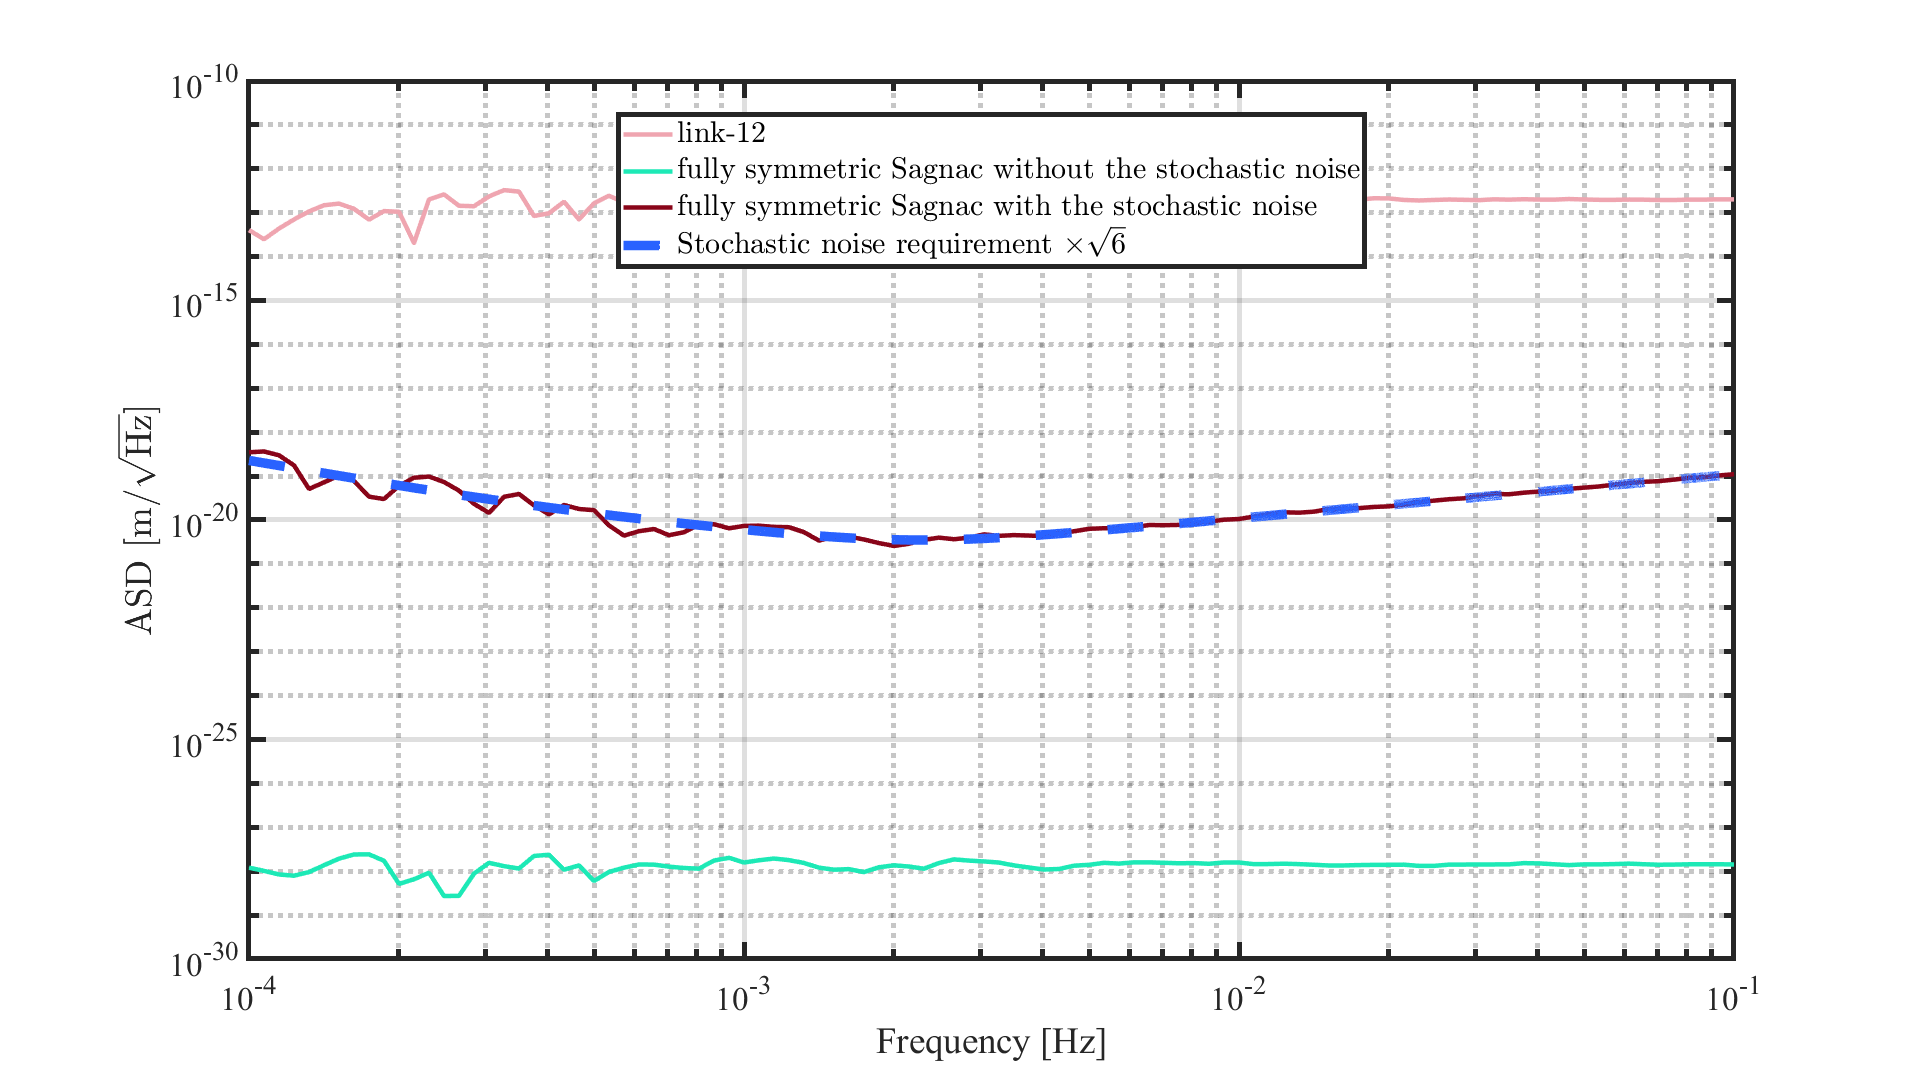

% --- %
% TDI %
% --- %
% delay the measurements
s_21_delayed_no = timeshift(s_21_no, L/c*fs, len_filter);
s_31_delayed_no = timeshift(s_31_no, L/c*fs, len_filter);
s_12_delayed_no = timeshift(s_12_no, L/c*fs, len_filter);
s_23_delayed_no = timeshift(s_23_no, L/c*fs, len_filter);
s_32_delayed_no = timeshift(s_32_no, L/c*fs, len_filter);
s_13_delayed_no = timeshift(s_13_no, L/c*fs, len_filter);
s_21_delayed_ye = timeshift(s_21_ye, L/c*fs, len_filter);
s_31_delayed_ye = timeshift(s_31_ye, L/c*fs, len_filter);
s_12_delayed_ye = timeshift(s_12_ye, L/c*fs, len_filter);
s_23_delayed_ye = timeshift(s_23_ye, L/c*fs, len_filter);
s_32_delayed_ye = timeshift(s_32_ye, L/c*fs, len_filter);
s_13_delayed_ye = timeshift(s_13_ye, L/c*fs, len_filter);
% fully symmetric Sagnac for no stochastic noise
X_no = s_12_delayed_no + s_23_delayed_no + s_31_delayed_no ...
    - s_13_delayed_no - s_32_delayed_no - s_21_delayed_no;
% fully symmetric Sagnac for with stochastic noise
X_ye = s_12_delayed_ye + s_23_delayed_ye + s_31_delayed_ye ...
    - s_13_delayed_ye - s_32_delayed_ye - s_21_delayed_ye;
new_figure;
[X_Xno, f_Xno, C_Xno] = lpsd(X_no, ...
    @hann, 1e-4, 1e-1, 100, 1, 1, fs, 0.9);
[X_Xye, f_Xye, C_Xye] = lpsd(X_ye, ...
    @hann, 1e-4, 1e-1, 100, 1, 1, fs, 0.9);
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f_Xno, sqrt(X_Xno .* C_Xno.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#1DE9B6"); hold on;
loglog(f_Xye, sqrt(X_Xye .* C_Xye.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#890519"); hold on;
loglog(f, S_n(f) * sqrt(6), "LineWidth", 5.7, ...
    "LineStyle", "--", "Color", "#2962FF")
legend("link-12", "fully symmetric Sagnac without the stochastic noise", ...
    "fully symmetric Sagnac with the stochastic noise", ...
    "Stochastic noise requirement $\times \sqrt{6}$", ...
    "location", "best", 'Interpreter', 'latex')
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

Y = [
    s_12_ye, ...
    s_23_ye, ...
    s_31_ye, ...
    s_13_ye, ...
    s_32_ye, ...
    s_21_ye];
clear s_*_* laser* lowpass* stochastic* white X_ye

## APCI

APCI is introduced by Baghi. 

- Form the measurements of the science interferometres as


$$Y=\left(s_{12} ,s_{23} ,s_{31} ,s_{13} ,s_{21} ,s_{32} \right),$$



$$X=\left(D_{-n_h } Y,D_{-n_h +1} Y,\ldotp \ldotp \ldotp ,D_{n_h } Y\right),$$



$$D_m s_n =\left\lbrace \begin{array}{ll}
s_{n-m}  & \textrm{if}\;n\in \left\lbrack n_{\min } ,n_{\max } \right\rbrack \\
0 & \textrm{otherwise}
\end{array}\right.$$


                where $n_{\min } =\max \left(0,m\right),n_{\max } =\min \left(N-1,N-1+m\right)$.

- Compute the PCs through SVD


$$X={\textrm{USV}}^T ,\;T=\textrm{XV}$$


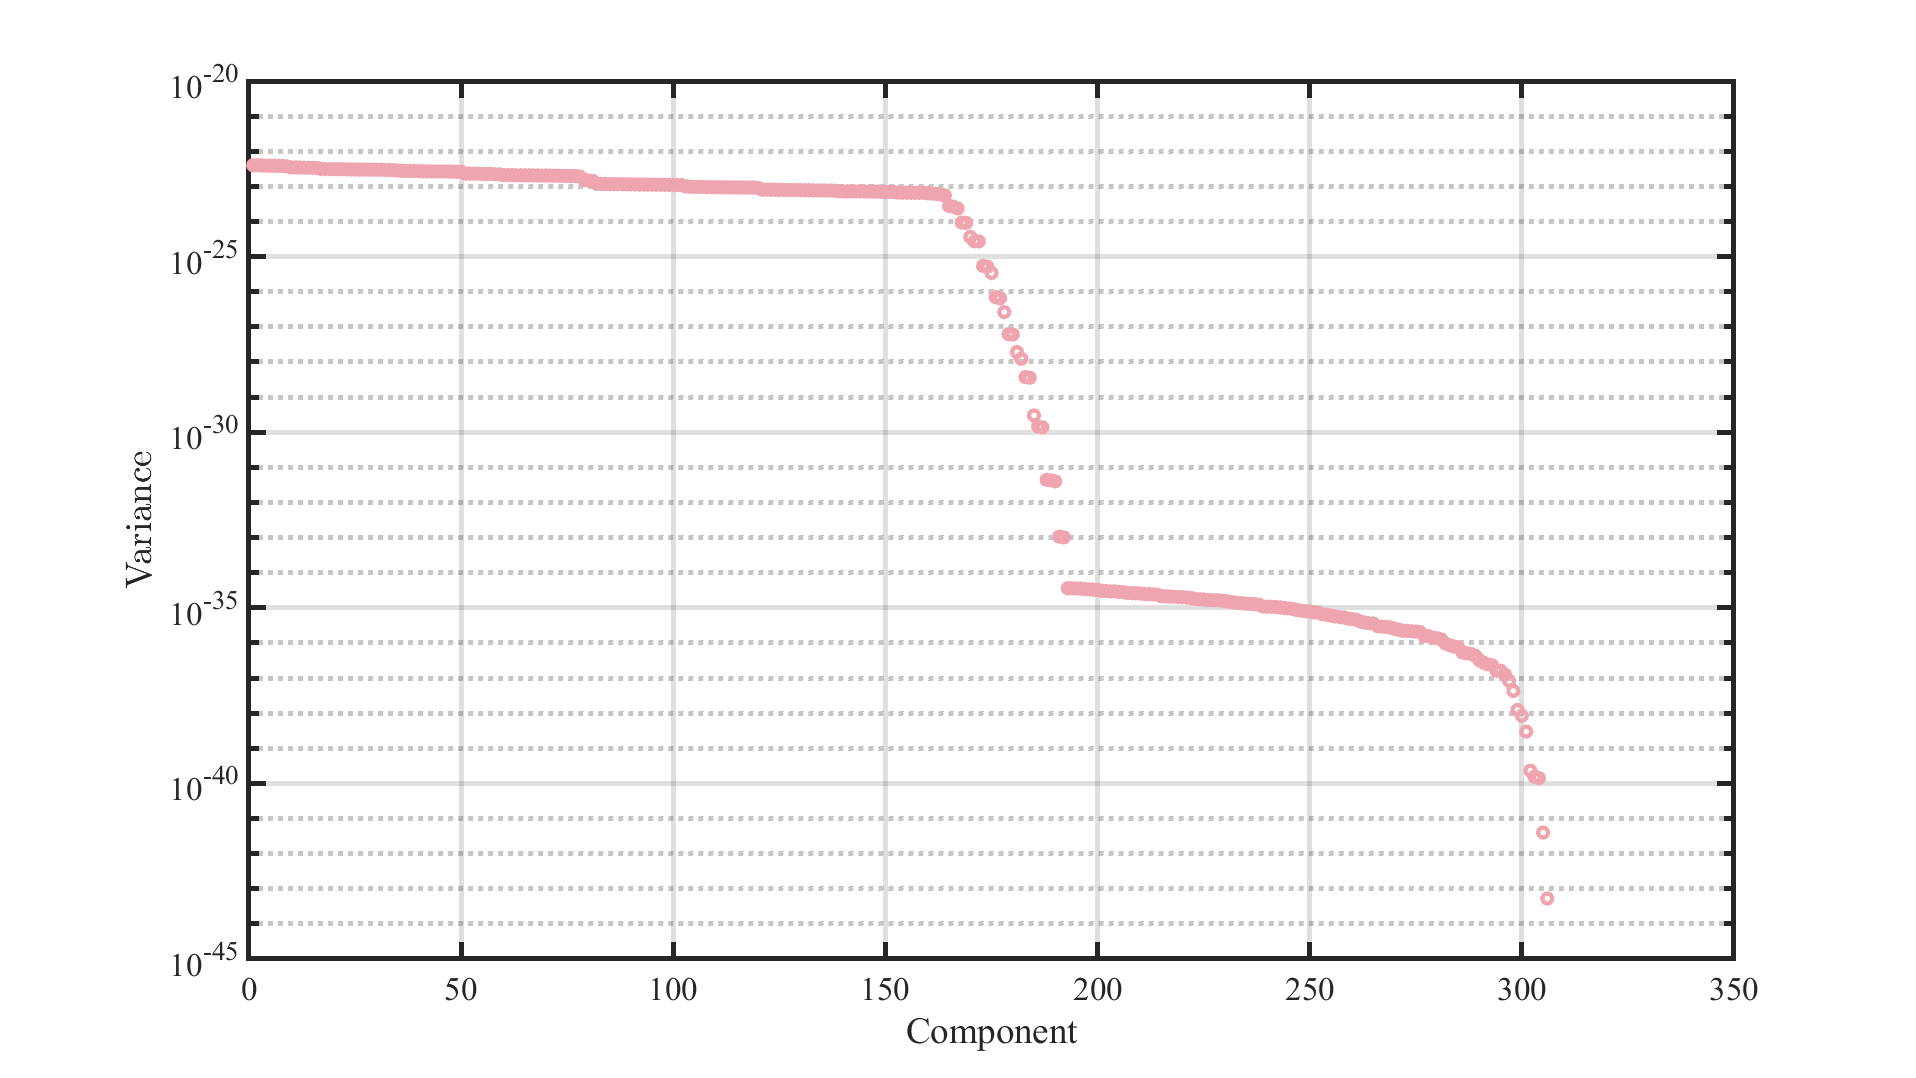

% form Y
X = zeros(length(Y), 6 * p);

for m = -n_h: n_h
    n_min = max(1, m + 1);
    n_max = min(length(Y), length(Y) + m);
    X(n_min: n_max, 6 * (m + n_h) + 1) = Y(n_min - m: n_max - m, 1);
    X(n_min: n_max, 6 * (m + n_h) + 2) = Y(n_min - m: n_max - m, 2);
    X(n_min: n_max, 6 * (m + n_h) + 3) = Y(n_min - m: n_max - m, 3);
    X(n_min: n_max, 6 * (m + n_h) + 4) = Y(n_min - m: n_max - m, 4);
    X(n_min: n_max, 6 * (m + n_h) + 5) = Y(n_min - m: n_max - m, 5);
    X(n_min: n_max, 6 * (m + n_h) + 6) = Y(n_min - m: n_max - m, 6);
end
X = X(n_h: end - n_h, :);
% svd
[~, S, V] =  svd(X, "econ");
T = X * V(:, end - 2: end);
new_figure;
semilogy(1: 6 * p, diag(S).^2 / (6 * p - 1), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "Marker", "o", "linestyle", "none"); hold on;
grid on;
hold on;
xlabel('Component', 'fontsize', 15);
ylabel('Variance', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

[X_1, f_1, C_1] = lpsd(T(:, 1), ...
    @hann, 1e-4, 1e-1, 1000, 1, 1, fs, 0.99);
[X_2, f_2, C_2] = lpsd(T(:, 2), ...
    @hann, 1e-4, 1e-1, 1000, 1, 1, fs, 0.99);
[X_3, f_3, C_3] = lpsd(T(:, 3), ...
    @hann, 1e-4, 1e-1, 1000, 1, 1, fs, 0.99);

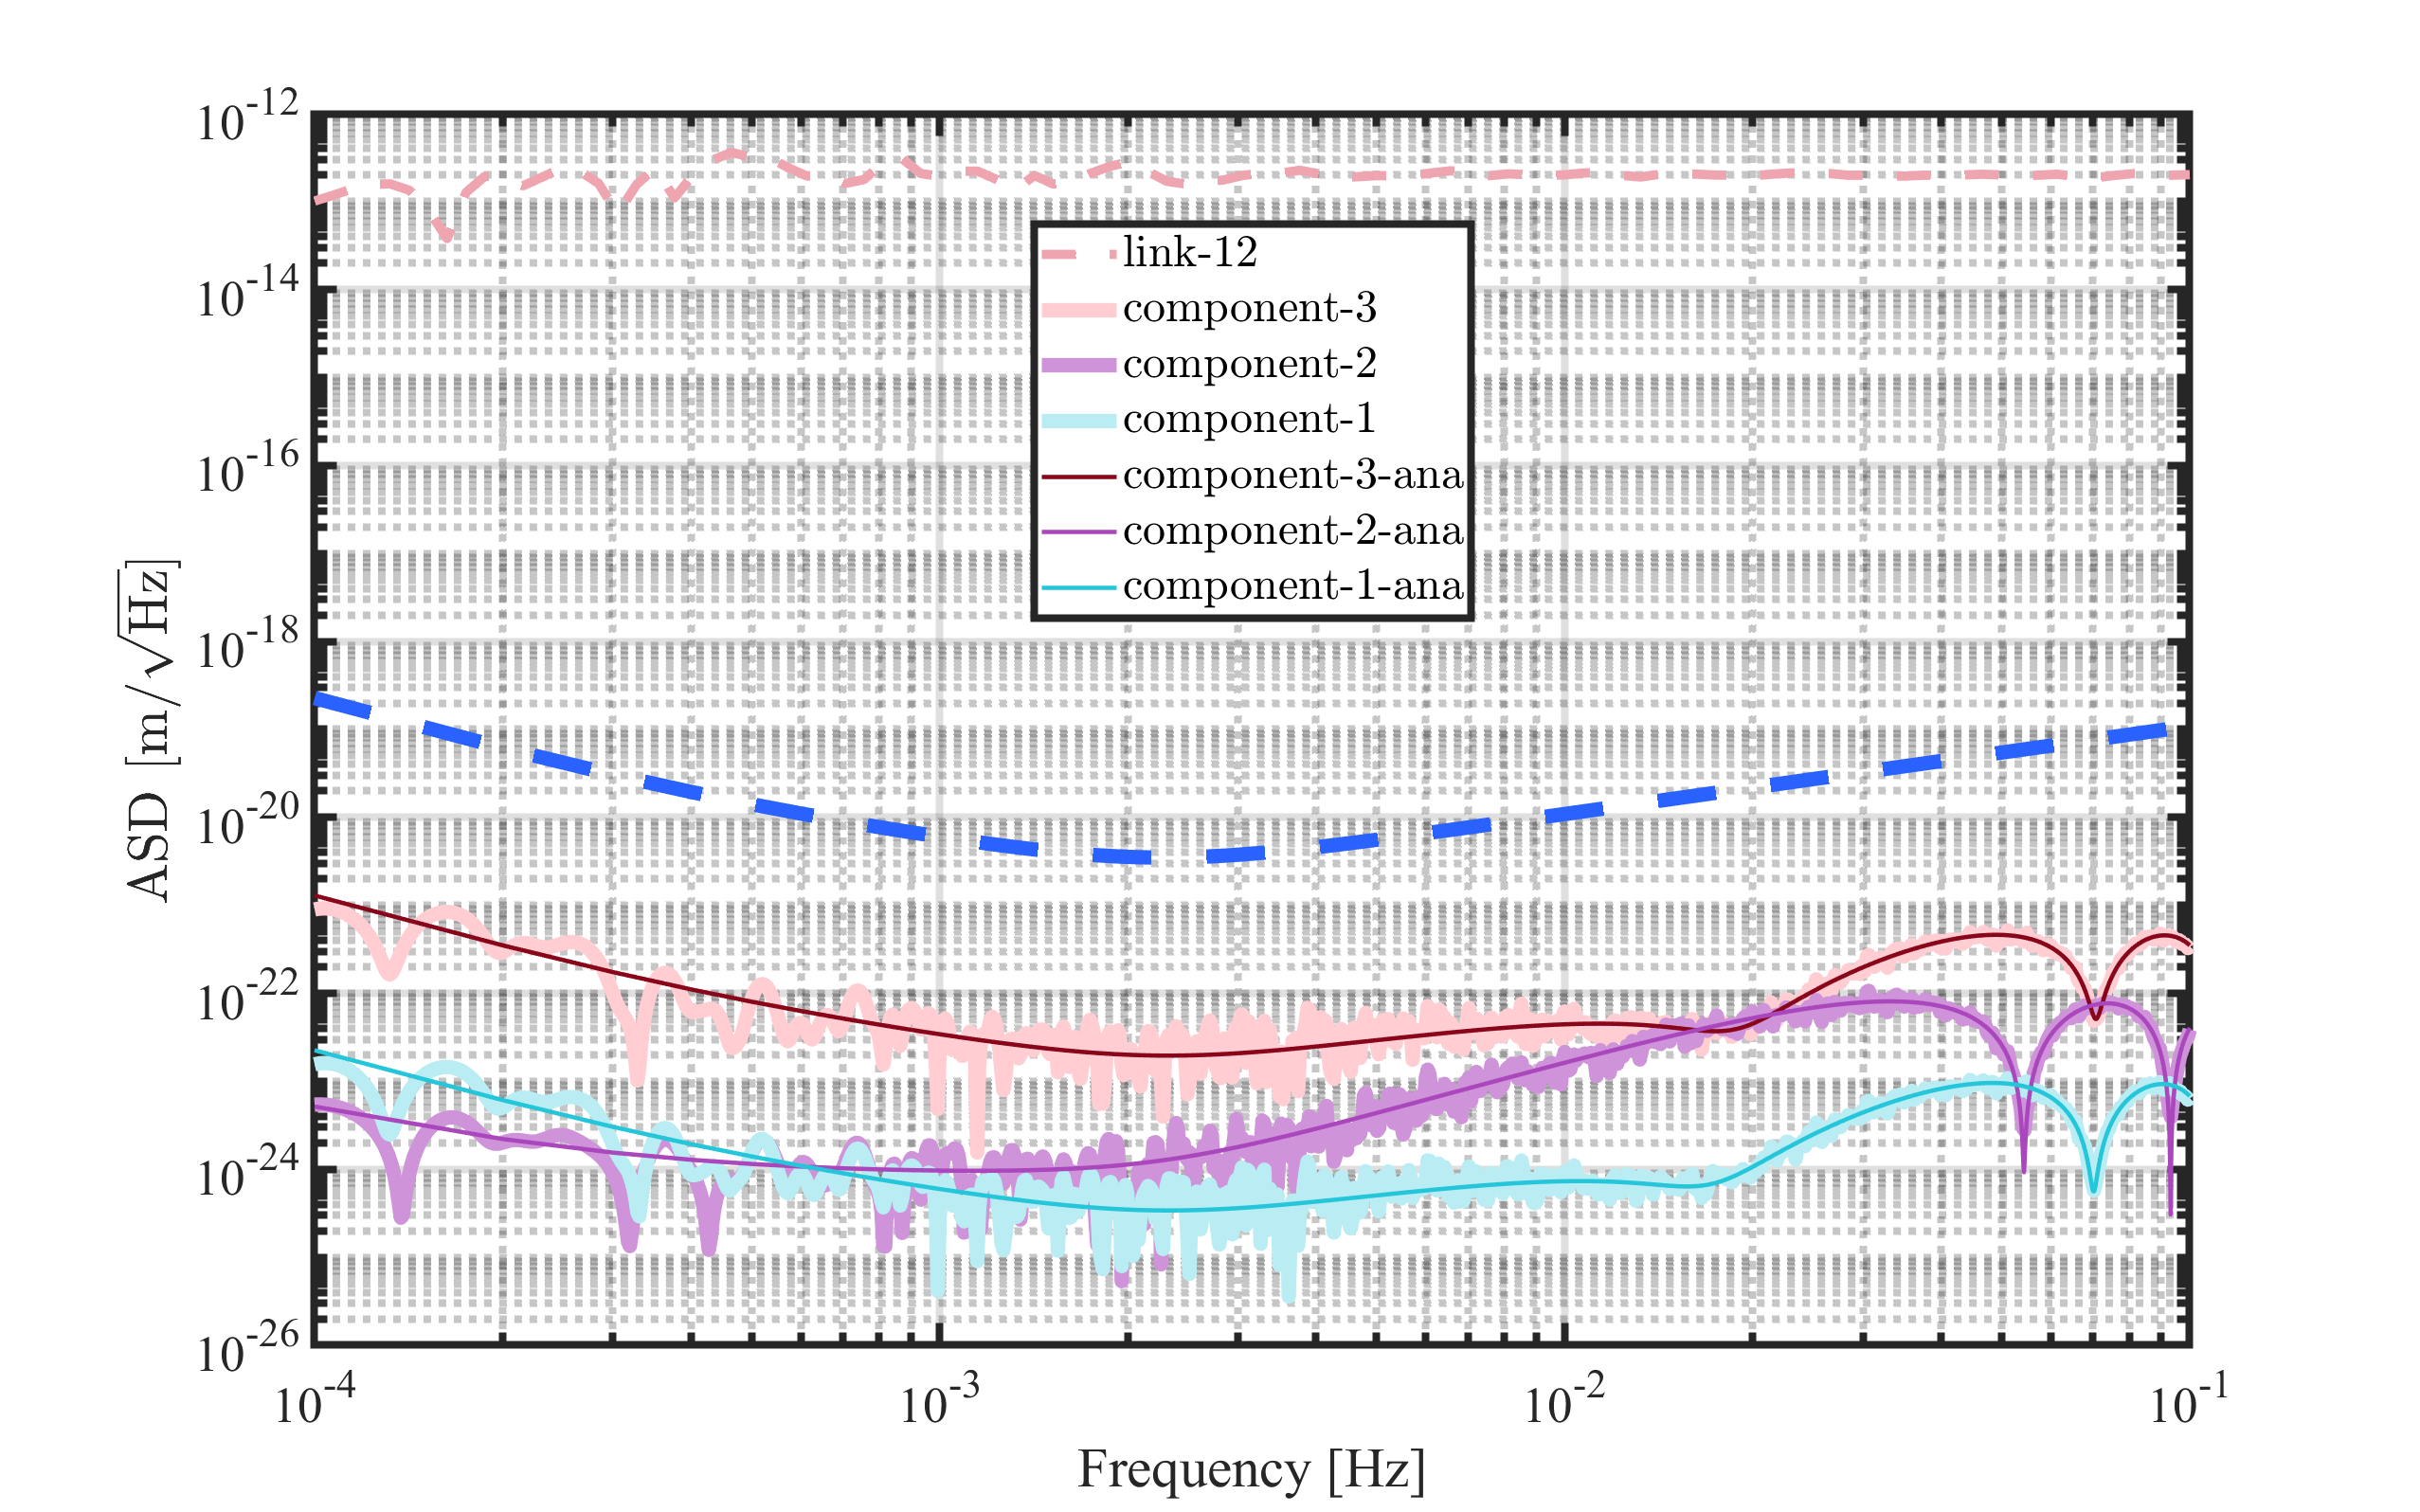

% [Pxx1, F1] = pcov(T(:, 1), 100, 20000, fs);
% [Pxx2, F2] = pcov(T(:, 2), 100, 20000, fs);
% [Pxx3, F3] = pcov(T(:, 3), 100, 20000, fs);
[z, f] = theoreticalPSD(V, n_h, fs, Y, S_n);
F3 = f; F2 = F3; F1 = F2;
Pxx1 = z(:, end - 2); Pxx2 = z(:, end - 1); Pxx3 = z(:, end - 0); 
new_figure;
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 3.7, ...
    "LineStyle", "--", "Color", "#EFA5B0"); hold on;
loglog(f_1, sqrt(X_1 .* C_1.PSD), 'linewidth', 5.7, ...
    "LineStyle", "-", "Color", c_l(1)); hold on;
loglog(f_2, sqrt(X_2 .* C_2.PSD), 'linewidth', 5.7, ...
    "LineStyle", "-", "Color", c_l(3)); hold on;
loglog(f_3, sqrt(X_3 .* C_3.PSD), 'linewidth', 5.7, ...
    "LineStyle", "-", "Color", c_l(5)); hold on;
loglog(F1, sqrt(Pxx1), 'linewidth', 1.7, ...
    "LineStyle", "-", "Color", c_d(1)); hold on;
loglog(F2, sqrt(Pxx2), 'linewidth', 1.7, ...
    "LineStyle", "-", "Color", c_d(3)); hold on;
loglog(F3, sqrt(Pxx3), 'linewidth', 1.7, ...
    "LineStyle", "-", "Color", c_d(5)); hold on;
loglog(f, S_n(f) * sqrt(6), "LineWidth", 5.7, ...
    "LineStyle", "--", "Color", "#2962FF", "DisplayName", "Stochastic noise requirement"); hold on
legend("link-12", ...
    "component-3", ...
    "component-2", ...
    "component-1", ...
    "component-3-ana", ...
    "component-2-ana", ...
    "component-1-ana", ...
    "location", "best", 'Interpreter', 'latex')
grid on;
hold on;
xlim([1e-4, 1e-1]);
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

Next, we will discuss the situation when some samples are missing.

### Direct combination from missing data *X*

We will replace missing data with zero when projecting the vector to subspace. Because one missing sample will appear in 51 rows in *Y, *every missing sample will lead 51 missing data in TDI combinations.

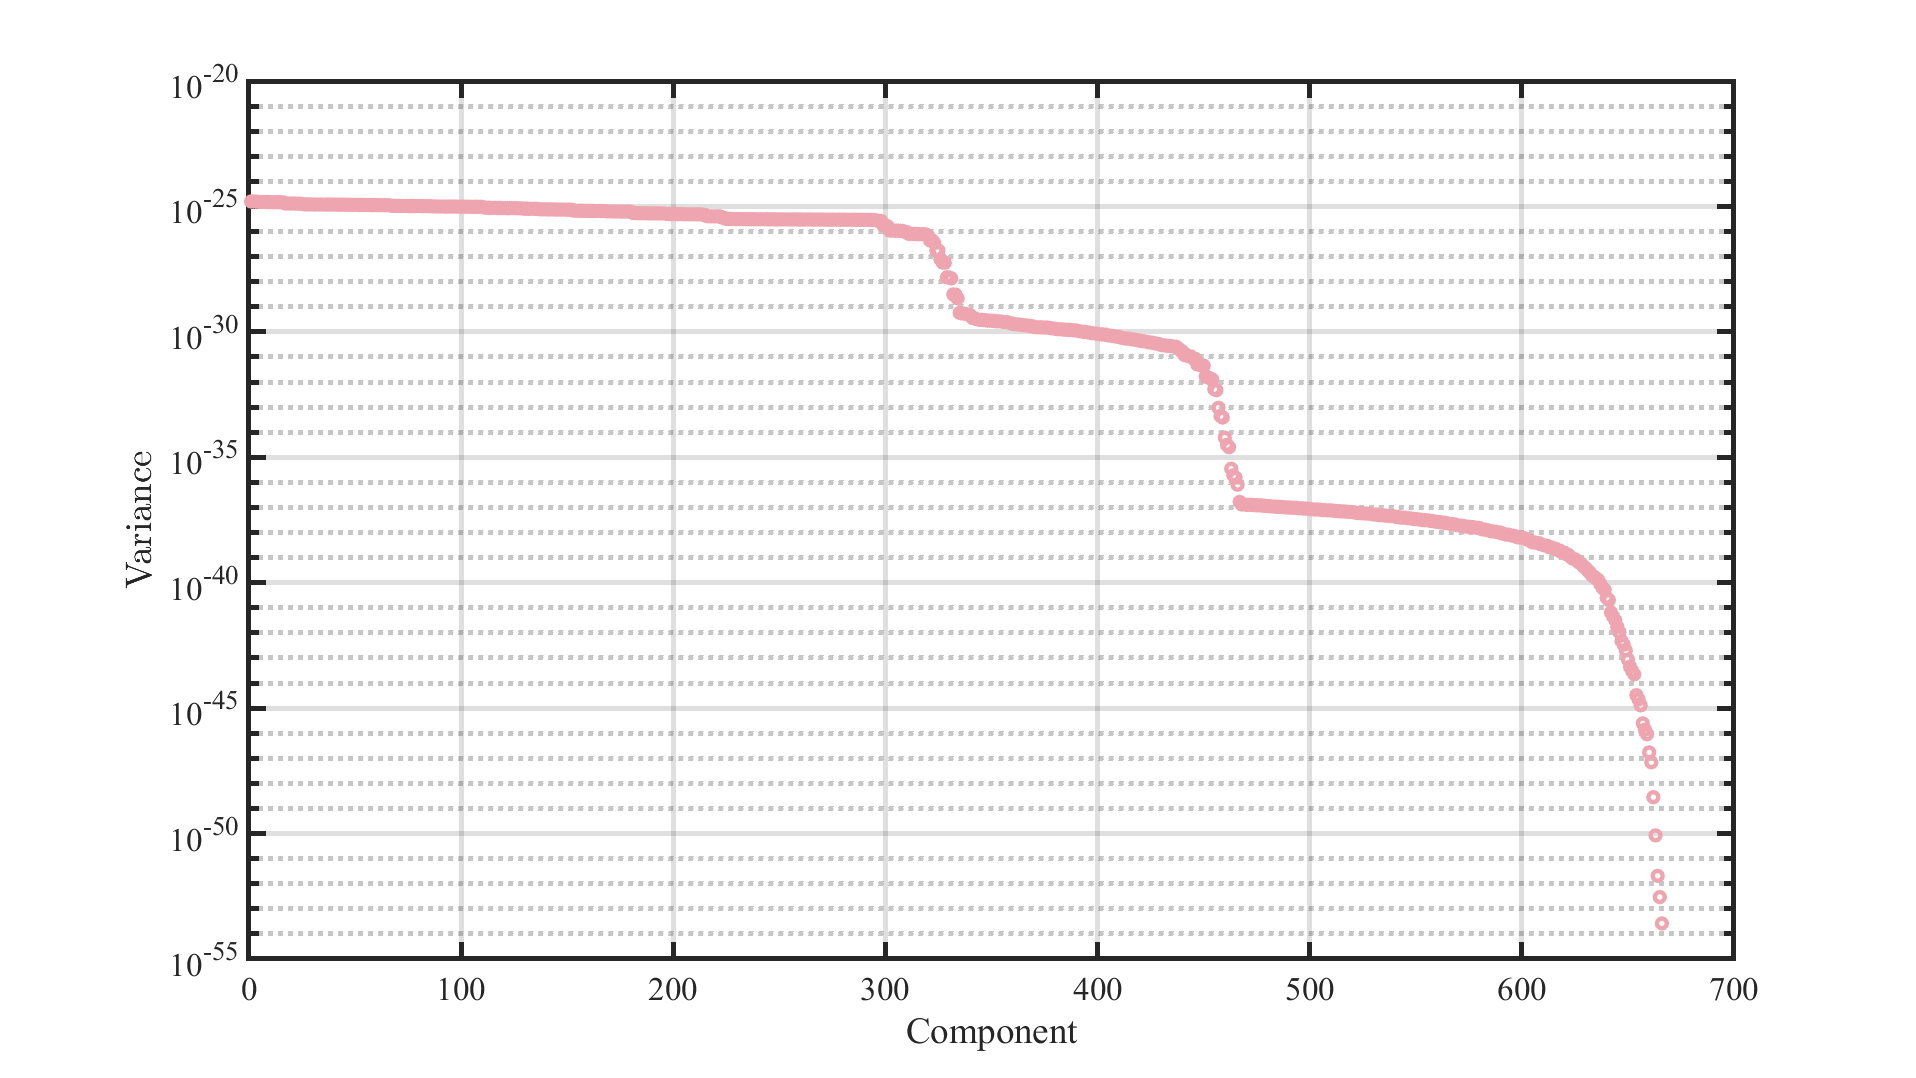

% form Y
X_missing1 = zeros(length(s_12_ye), 6 * p);
ix = random('unif', 0, 1, size(Y)) < 0.001;
Y(ix) = nan;

for m = -n_h: n_h
    n_min = max(1, m + 1);
    n_max = min(length(s_12_ye), length(s_12_ye) + m);
    X_missing1(n_min: n_max, 6 * (m + n_h) + 1) = Y(n_min - m: n_max - m, 1);
    X_missing1(n_min: n_max, 6 * (m + n_h) + 2) = Y(n_min - m: n_max - m, 2);
    X_missing1(n_min: n_max, 6 * (m + n_h) + 3) = Y(n_min - m: n_max - m, 3);
    X_missing1(n_min: n_max, 6 * (m + n_h) + 4) = Y(n_min - m: n_max - m, 4);
    X_missing1(n_min: n_max, 6 * (m + n_h) + 5) = Y(n_min - m: n_max - m, 5);
    X_missing1(n_min: n_max, 6 * (m + n_h) + 6) = Y(n_min - m: n_max - m, 6);
end

% pca complete
[~, score, pcvar, ~] = pca(X_missing1, 'Rows', 'complete');
score(isnan(score)) = 0;
new_figure;
semilogy(1: 6 * p, pcvar, 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "Marker", "o", "linestyle", "none"); hold on;
grid on;
hold on;
xlabel('Component', 'fontsize', 15);
ylabel('Variance', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

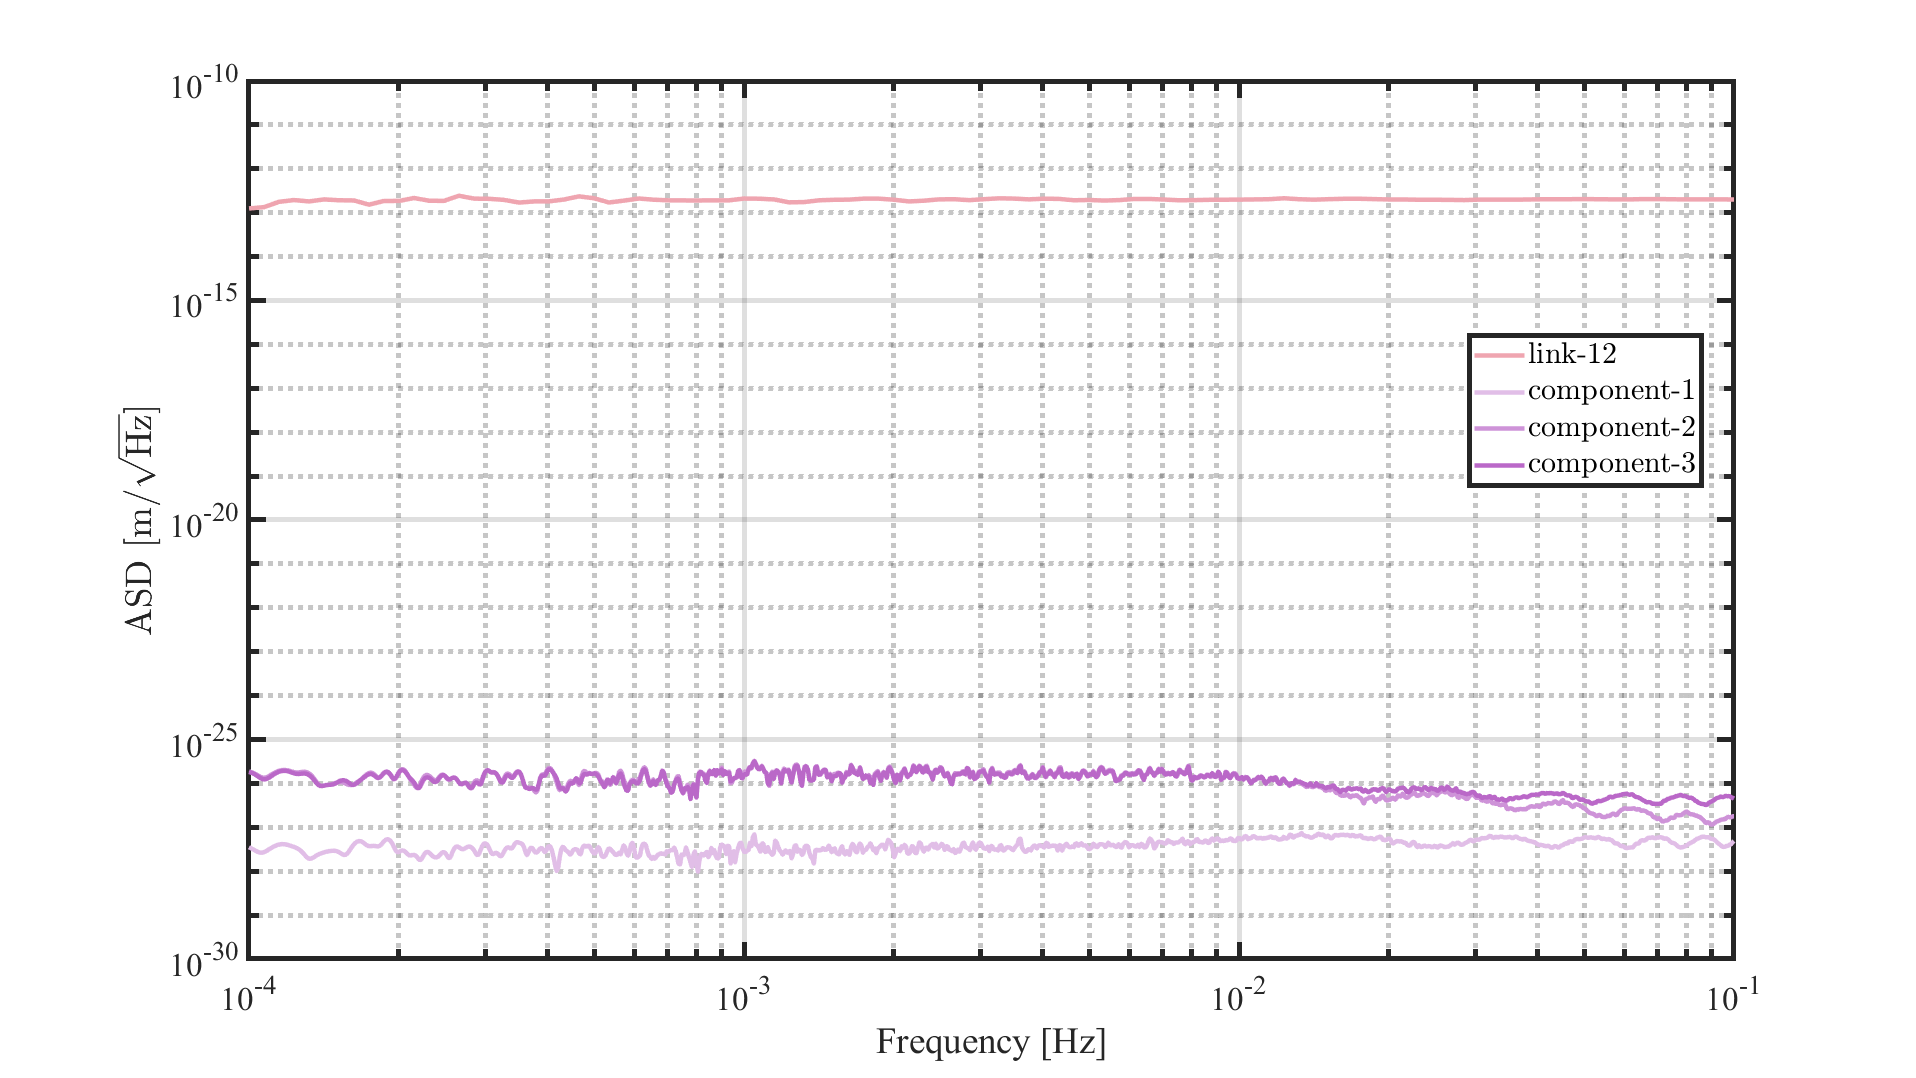

new_figure;
[X_1, f_1, C_1] = lpsd(score(:, end - 0), ...
    @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
[X_2, f_2, C_2] = lpsd(score(:, end - 1), ...
    @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
[X_3, f_3, C_3] = lpsd(score(:, end - 2), ...
    @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f_1, sqrt(X_1 .* C_1.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#E1BEE7"); hold on;
loglog(f_2, sqrt(X_2 .* C_2.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#CE93D8"); hold on;
loglog(f_3, sqrt(X_3 .* C_3.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#BA68C8"); hold on;
legend("link-12", "component-1", ...
    "component-2", ...
    "component-3", ...
    "location", "best", 'Interpreter', 'latex')
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

### Combination disregarding missing data 

We will disregard the rows of *X* where the missing data appear, and then reform *X* into *Y*.

Y(any(isnan(Y), 2), :) = [];
X_missing2 = zeros(length(Y), 6);
for m = -n_h: n_h
    n_min = max(1, m + 1);
    n_max = min(length(Y), length(Y) + m);
    X_missing2(n_min: n_max, 6 * (m + n_h) + 1) = Y(n_min - m: n_max - m, 1);
    X_missing2(n_min: n_max, 6 * (m + n_h) + 2) = Y(n_min - m: n_max - m, 2);
    X_missing2(n_min: n_max, 6 * (m + n_h) + 3) = Y(n_min - m: n_max - m, 3);
    X_missing2(n_min: n_max, 6 * (m + n_h) + 4) = Y(n_min - m: n_max - m, 4);
    X_missing2(n_min: n_max, 6 * (m + n_h) + 5) = Y(n_min - m: n_max - m, 5);
    X_missing2(n_min: n_max, 6 * (m + n_h) + 6) = Y(n_min - m: n_max - m, 6);
end

% pca complete
[~, score, pcvar, ~] = pca(X_missing2);

Out of memory.

Error in pca>localTSquared (line 521)
tsquared = sum(standScores.^2, 2);

Error in pca (line 361)
                tsquared = localTSquared(score,latent,DOF,p);

Related documentation

score(isnan(score)) = 0;
new_figure;
semilogy(1: 6 * p, pcvar, 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "Marker", "o", "linestyle", "none"); hold on;
grid on;
hold on;
xlabel('Component', 'fontsize', 15);
ylabel('Variance', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
new_figure;
[X_1, f_1, C_1] = lpsd(score(:, end - 0), ...
    @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
[X_2, f_2, C_2] = lpsd(score(:, end - 1), ...
    @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
[X_3, f_3, C_3] = lpsd(score(:, end - 2), ...
    @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f_1, sqrt(X_1 .* C_1.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#E1BEE7"); hold on;
loglog(f_2, sqrt(X_2 .* C_2.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#CE93D8"); hold on;
loglog(f_3, sqrt(X_3 .* C_3.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#BA68C8"); hold on;
legend("link-12", "component-1", ...
    "component-2", ...
    "component-3", ...
    "location", "best", 'Interpreter', 'latex')
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

### Combination when one measurement is missing for a long period

% form Y
% nh
n_h = 55;
% p
p = n_h * 2 + 1;
X_missing3 = zeros(length(s_12_ye), 5 * p);
Y = [
    s_12_ye, ...
    s_23_ye, ...
    s_31_ye, ...
    s_13_ye, ...
    s_32_ye, ...
    s_21_ye];
Y(:, 1) = [];

[rows, cols] = size(Y);

for m = -n_h: n_h
    n_min = max(1, m + 1);
    n_max = min(length(s_12_ye), length(s_12_ye) + m);
    X_missing3(n_min: n_max, cols * (m + n_h) + 1) = Y(n_min - m: n_max - m, 1);
    X_missing3(n_min: n_max, cols * (m + n_h) + 2) = Y(n_min - m: n_max - m, 2);
    X_missing3(n_min: n_max, cols * (m + n_h) + 3) = Y(n_min - m: n_max - m, 3);
    X_missing3(n_min: n_max, cols * (m + n_h) + 4) = Y(n_min - m: n_max - m, 4);
    X_missing3(n_min: n_max, cols * (m + n_h) + 5) = Y(n_min - m: n_max - m, 5);
end
% svd
[~, S, V] =  svd(X_missing3, "econ");
score = X_missing3 * V;
new_figure;
semilogy(1: 5 * p, diag(S).^2 / (5 * p - 1), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "Marker", "o", "linestyle", "none"); hold on;
grid on;
hold on;
xlabel('Component', 'fontsize', 15);
ylabel('Variance', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
new_figure;
color_map = [
    "#A8EEED", ...
    "#ACDCF0", ...
    "#B0CBF1", ...
    "#B3BBF2", ...
    "#C2B7F3", ...
    "#FEFFE8", ...
    "#FFF8E3", ...
    "#FFEDDE", ...
    "#FEDFD9", ...
    "#FED5DB"];
for k = 0: 2
    [X_1, f_1, C_1] = lpsd(score(:, end - k), ...
        @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
    loglog(f_1, sqrt(X_1 .* C_1.PSD), 'linewidth', 2.7, ...
        "LineStyle", "-", "Color", color_map(k + 1), 'DisplayName', ['component-', num2str(k + 1)]); hold on;
end
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "DisplayName", "link-12"); hold on
loglog(f, S_n(f) * sqrt(6), "LineWidth", 5.7, ...
    "LineStyle", "--", "Color", "#2962FF", "DisplayName", "Stochastic noise requirement"); hold on
grid on;
legend show
yline(1e-21, "linewidth", 3, "color", "g", "DisplayName", "1e-21")
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 18, "fontname", "Times New Roman", "linewidth", 2, 'YScale', 'log', 'XScale', 'log');

## Sensitivity

### Motion of Taiji

armlength equals to 3e9 m.

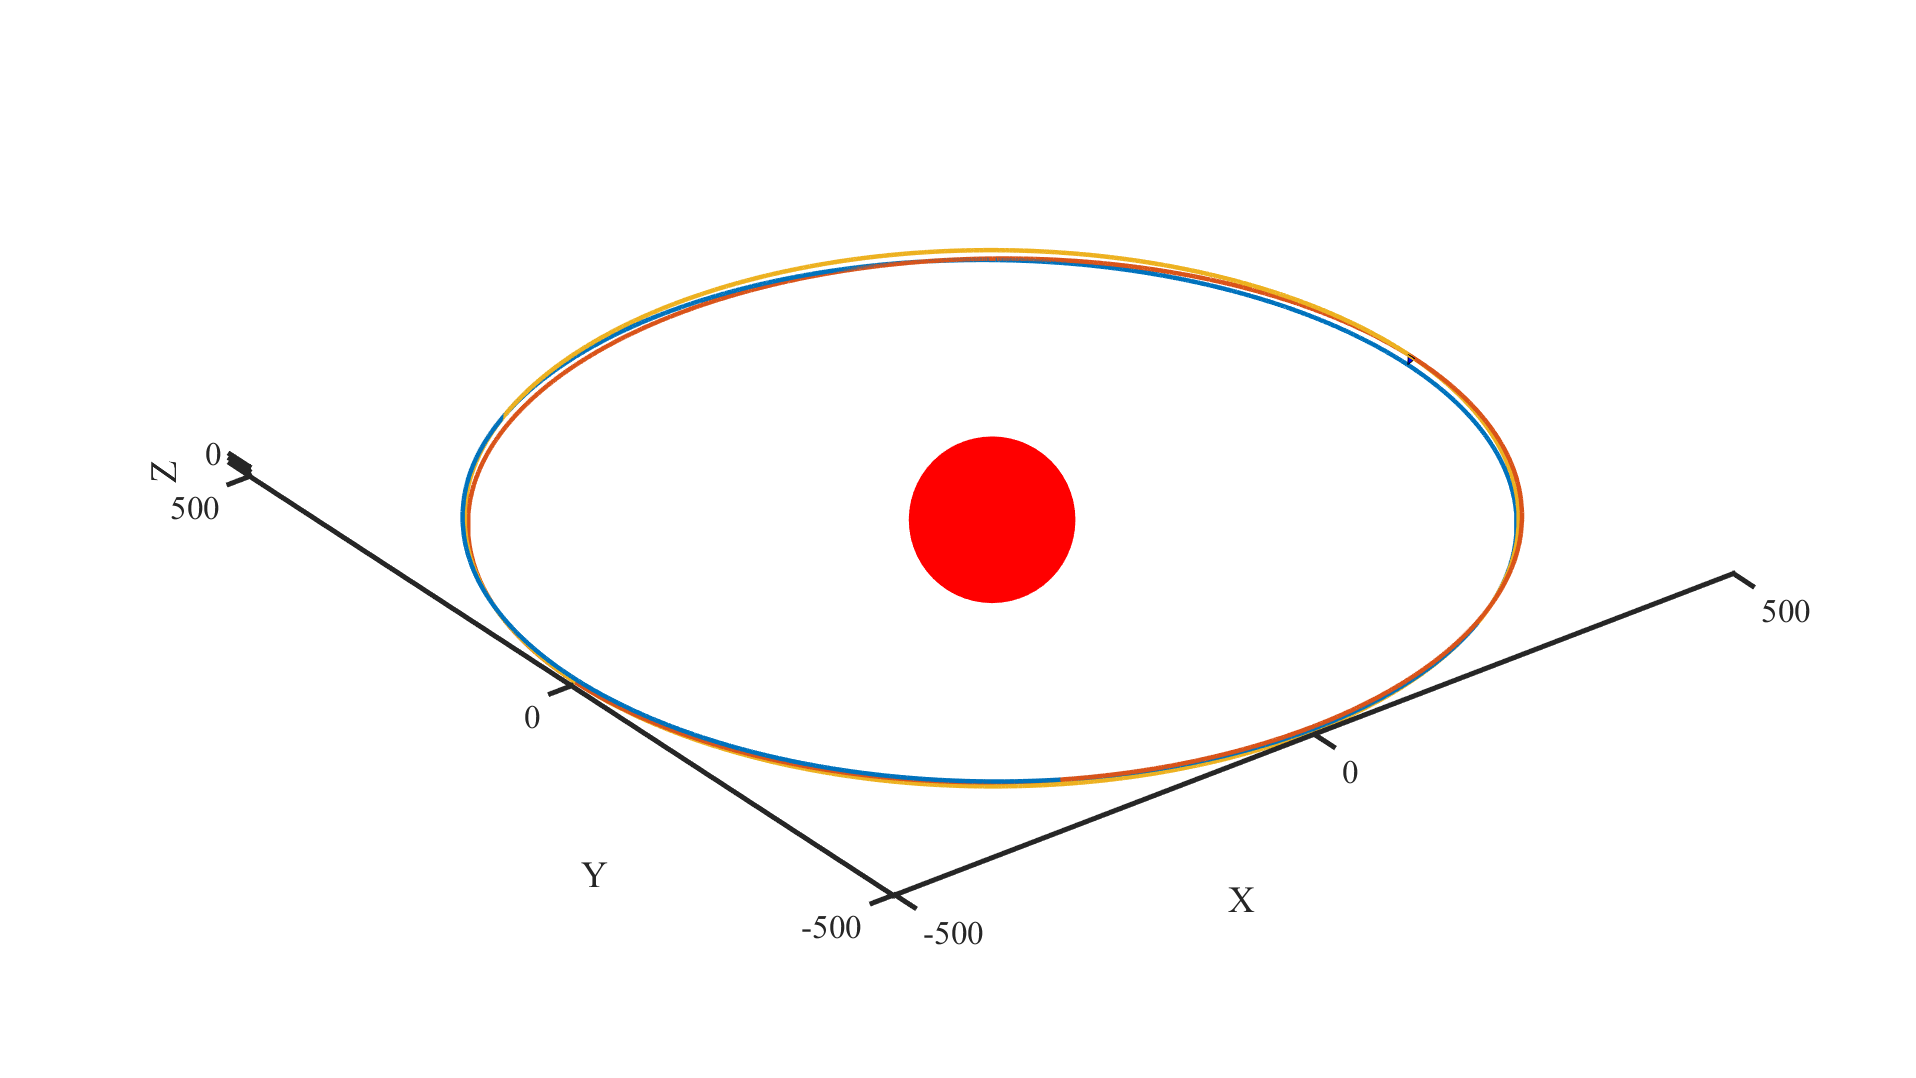

[n23, n31, n12] = TaijiMotion(1: 1000: year);

esponse

## PPCA-TDI

opt = statset('ppca');
opt.TolFun = 1e-20;
opt.Display = 'iter';
opt.MaxIter = 1000;
opt.TolX = 1e-20;
opt.UseParallel = true; 
factor = 1e0;
[coeff0, ~, pcvar0, mu0, v0, S0] = ppca(X(1: 30000, :) * factor, 6 * p, "options", opt);


Iteration     Variance    |Delta X|   Negative Log-likelihood:
        1     0.000000 295431591.218651   -256178372.790511

Final root mean square residual = 1.83769e-13.


score0 = X(1: 30000, :) * coeff0;
% opt.MaxIter = 10;
% [coeff1, score1, pcvar1, mu1, v1, S1] = ppca(X_missing1(1: 500, :) * factor, 6 * p, "options", opt);
[coeff2, ~, pcvar2, mu2, v2, S2] = ppca(X_missing2(1: 30000, :) * factor, 6 * p, "options", opt);

Unrecognized function or variable 'X_missing2'.

score2 = X_missing2(1: 30000, :) * coeff2;
[coeff3, ~, pcvar3, mu3, v3, S3] = ppca(X_missing3(1: 30000, :) * factor, 5 * p, "options", opt);
score3 = X_missing3(1: 30000, :) * coeff3;
new_figure;
semilogy(1: 6 * p - 1, pcvar0 / factor^2, 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "Marker", "o", "linestyle", "none"); hold on;
grid on;
hold on;
xlabel('Component Index', 'fontsize', 15);
ylabel('Variance', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
new_figure;
color_map = [
    "#A8EEED", ...
    "#ACDCF0", ...
    "#B0CBF1", ...
    "#B3BBF2", ...
    "#C2B7F3", ...
    "#FEFFE8", ...
    "#FFF8E3", ...
    "#FFEDDE", ...
    "#FEDFD9", ...
    "#FED5DB"];
for k = 0: 2
    [X_1, f_1, C_1] = lpsd(score0(100: end - 100, end - k), ...
        @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
    loglog(f_1, sqrt(X_1 .* C_1.PSD), 'linewidth', 2.7, ...
        "LineStyle", "-", "Color", color_map(k + 1), 'DisplayName', ['component-', num2str(k + 1)]); hold on;
end
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "DisplayName", "link-12"); hold on
loglog(f, S_n(f) * sqrt(6), "LineWidth", 5.7, ...
    "LineStyle", "--", "Color", "#2962FF", "DisplayName", "Stochastic noise requirement"); hold on
grid on;
legend show
yline(1e-21, "linewidth", 3, "color", "g", "DisplayName", "1e-21")
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 18, "fontname", "Times New Roman", "linewidth", 2, 'YScale', 'log', 'XScale', 'log');
new_figure;
semilogy(1: 6 * p - 1, pcvar2 / factor^2, 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "Marker", "o", "linestyle", "none"); hold on;
grid on;
hold on;
xlabel('Component Index', 'fontsize', 15);
ylabel('Variance', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
new_figure;
color_map = [
    "#A8EEED", ...
    "#ACDCF0", ...
    "#B0CBF1", ...
    "#B3BBF2", ...
    "#C2B7F3", ...
    "#FEFFE8", ...
    "#FFF8E3", ...
    "#FFEDDE", ...
    "#FEDFD9", ...
    "#FED5DB"];
for k = 0: 2
    [X_1, f_1, C_1] = lpsd(score2(100: end - 100, end - k), ...
        @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
    loglog(f_1, sqrt(X_1 .* C_1.PSD), 'linewidth', 2.7, ...
        "LineStyle", "-", "Color", color_map(k + 1), 'DisplayName', ['component-', num2str(k + 1)]); hold on;
end
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "DisplayName", "link-12"); hold on
loglog(f, S_n(f) * sqrt(6), "LineWidth", 5.7, ...
    "LineStyle", "--", "Color", "#2962FF", "DisplayName", "Stochastic noise requirement"); hold on
grid on;
legend show
yline(1e-21, "linewidth", 3, "color", "g", "DisplayName", "1e-21")
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 18, "fontname", "Times New Roman", "linewidth", 2, 'YScale', 'log', 'XScale', 'log');
new_figure;
semilogy(1: 5 * p - 1, pcvar3 / factor^2, 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "Marker", "o", "linestyle", "none"); hold on;
grid on;
hold on;
xlabel('Component Index', 'fontsize', 15);
ylabel('Variance', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
new_figure;
color_map = [
    "#A8EEED", ...
    "#ACDCF0", ...
    "#B0CBF1", ...
    "#B3BBF2", ...
    "#C2B7F3", ...
    "#FEFFE8", ...
    "#FFF8E3", ...
    "#FFEDDE", ...
    "#FEDFD9", ...
    "#FED5DB"];
for k = 0: 2
    [X_1, f_1, C_1] = lpsd(score3(100: end - 100, end - k), ...
        @hann, 1e-4, 1e-1, 1000, 10, 10, fs, 0.9);
    loglog(f_1, sqrt(X_1 .* C_1.PSD), 'linewidth', 2.7, ...
        "LineStyle", "-", "Color", color_map(k + 1), 'DisplayName', ['component-', num2str(k + 1)]); hold on;
end
loglog(f_s12, sqrt(X_s12 .* C_s12.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0", "DisplayName", "link-12"); hold on
loglog(f, S_n(f) * sqrt(6), "LineWidth", 5.7, ...
    "LineStyle", "--", "Color", "#2962FF", "DisplayName", "Stochastic noise requirement"); hold on
grid on;
legend show
yline(1e-21, "linewidth", 3, "color", "g", "DisplayName", "1e-21")
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 18, "fontname", "Times New Roman", "linewidth", 2, 'YScale', 'log', 'XScale', 'log');